# Develop a Cartesian Robot Model Programmatically

This example shows how to assemble modular and reconfigurable components into a cartesian robot Simscape™ Multibody™ model in MATLAB®.

To return to the main page within this repository, [click here](matlab:web('CartesianRobotDesignOverview.html')).

## Identify the Robot Model and Components to Develop

The figure shows a Cartesian robot model with XY axes configuration. This robot is used in applications like assembling and packaging.

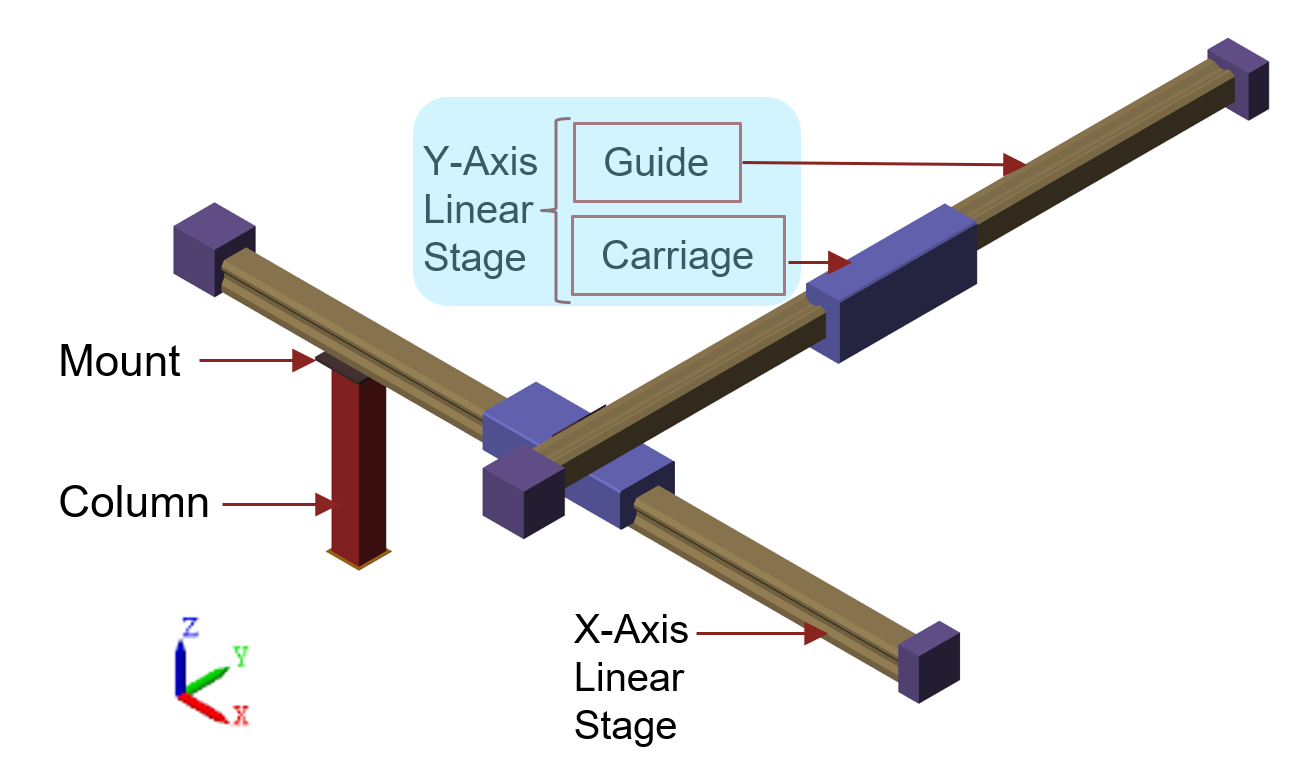

The robot has these components.

## Steps to Build the Robot Mechanism

A key principle to follow is to begin with a simple approximation to get the basic mechanism working and then in subsequent iterations add complexity to the model. The recommended model building process can be broken down into these steps:

- Identify the rigid bodies in the mechanism and how they are connected to each other.

- Consider each rigid body in isolation. Build a simple approximation of the rigid body, and define the frames rigidly attached to it.

- Assemble the rigid bodies by connecting via joints and/or constraints.

- Check and visualize the model assembly and identify any issues with it and fix issues.

- Configure assembly for a desired configuration by utilizing the operating points or `OperatingPoint` objects.

- Create a block diagram model from the `simscape.multibody.Multibody` object to simulate the system. To know more about `simscape.multibody.Multibody` objects, [click here](https://www.mathworks.com/help/sm/ref/simscape.multibody.multibody-class.html).

## Construct Rigid Bodies and Their Interfaces

### Identify Rigid Bodies and Their Connections

The robot consists of these rigid bodies:

- Column - There is one column which is rigidly connected to the world frame W.

- Mounts - There are two mounts. One plate mount is rigidly connected to the column and the X-Axis Linear Stage. One L-shaped mount is rigidly connected to the  X-Axis Linear Stage and Y-Axis Linear Stage.

- Guides and Carriages - There are two linear stages representing the X-Axis and the Y-Axis, respectively. Each linear stage consists of a guide and a carriage, connected via a Prismatic joint.

You can construct a rigid body by specifying its geometry, inertial properties and interface with other parts. Construct each rigid body in isolation.

### Construct the Columns

To instantly view a column, click on Visualize Column button below.

You can build a column using custom values. In this example, a column has three components - a pillar bounded by a top plate and a bottom plate. 

Specify geometry, inertia and graphic parameters of the pillar of the column.

MBObj.Column.lenthPillar  = 0.005; 
MBObj.Column.widthPillar  = 0.005;  
MBObj.Column.heightPillar   = 0.03; 
MBObj.Column.dimensionsPillar = simscape.Value([MBObj.Column.lenthPillar,MBObj.Column.widthPillar,MBObj.Column.heightPillar],"m");
MBObj.Column.densityColumn = simscape.Value(2700,"kg/m^3");
MBObj.Column.graphicPillar = [0.8 0.2 0.2];

Define frames of the pillar using the `simscape.multibody.RigidTransform` objects. 

MBObj.Column.rtPillarF1 = simscape.multibody.RigidTransform(simscape.multibody.StandardAxisTranslation(simscape.Value(0.5*MBObj.Column.heightPillar, "m"), ...
    simscape.multibody.Axis.NegZ));
MBObj.Column.rtPillarF2 = simscape.multibody.RigidTransform(simscape.multibody.StandardAxisTranslation(simscape.Value(0.5*MBObj.Column.heightPillar, "m"), ...
    simscape.multibody.Axis.PosZ));

Add a frame at each end of the pillar.

MBObj.Column.framesPillar = struct('F1',MBObj.Column.rtPillarF1,'F2',MBObj.Column.rtPillarF2);

Construct a rigid body of the pillar using the function `constructBrickRigidBody`.

MBObj.Column.pillarRB = constructBrickRigidBody(dimensions=MBObj.Column.dimensionsPillar,density=MBObj.Column.densityColumn,...
    graphic=MBObj.Column.graphicPillar,frames=MBObj.Column.framesPillar);

Specify geometry, inertia and graphic parameters of the top and bottom plates of the column.

MBObj.Column.lenthColumnPlate = 0.006;
MBObj.Column.widthColumnPlate = 0.006;
MBObj.Column.heightColumnPlate  = 0.0001;
MBObj.Column.dimensionsColPlate = simscape.Value([MBObj.Column.lenthColumnPlate,MBObj.Column.widthColumnPlate,MBObj.Column.heightColumnPlate],"m");
MBObj.Column.graphicColPlate = [0.8 0.5 0.1];

Define frames of the top and bottom plates using the `simscape.multibody.RigidTransform` objects. 

MBObj.Column.rtColumnBotPlateF1 = simscape.multibody.RigidTransform(simscape.multibody.CartesianTranslation(simscape.Value ...
    ([0 0 -0.5*MBObj.Column.heightColumnPlate],"m")));
MBObj.Column.rtColumnPlateF1 = simscape.multibody.RigidTransform(simscape.multibody.StandardAxisTranslation(simscape.Value ...
    (0.5*MBObj.Column.heightColumnPlate, "m"), simscape.multibody.Axis.NegZ));
MBObj.Column.rtColumnPlateF2 = simscape.multibody.RigidTransform(simscape.multibody.StandardAxisTranslation(simscape.Value ...
    (0.5*MBObj.Column.heightColumnPlate, "m"), simscape.multibody.Axis.PosZ));

Add a frame at each end of the bottom plate and top plate of the column.

MBObj.Column.framesBotPlateColumn = struct('F1',MBObj.Column.rtColumnBotPlateF1,'F2',MBObj.Column.rtColumnPlateF2);
MBObj.Column.framesTopPlateColumn = struct('F1',MBObj.Column.rtColumnPlateF1,'F2',MBObj.Column.rtColumnPlateF2);

Construct rigid bodies of the top and bottom plates respectively using the function `constructBrickRigidBody`.

MBObj.Column.bottomPlateColumnRB = constructBrickRigidBody(dimensions=MBObj.Column.dimensionsColPlate,density=MBObj.Column.densityColumn,...
    graphic=MBObj.Column.graphicColPlate,frames=MBObj.Column.framesBotPlateColumn);
MBObj.Column.topPlateColumnRB = constructBrickRigidBody(dimensions=MBObj.Column.dimensionsColPlate,density=MBObj.Column.densityColumn,...
    graphic=MBObj.Column.graphicColPlate,frames=MBObj.Column.framesTopPlateColumn);

Create a `simscape.multibody.Multibody` object to build a multibody system for the column. Add the rigid bodies for pillar, top plate and bottom plate respectively to the created multibody system using `addComponent` method of the `Multibody` object.

MBObj.Column.columnMB = simscape.multibody.Multibody;
addComponent(MBObj.Column.columnMB,"Pillar",MBObj.Column.pillarRB);
addComponent(MBObj.Column.columnMB,"TopPlateC",MBObj.Column.topPlateColumnRB);
addComponent(MBObj.Column.columnMB,"BottomPlateC",MBObj.Column.bottomPlateColumnRB);

Connect the rigid bodies in the Column multibody system using `connect` method of the `Multibody` object. In this example, the column is rigidly connected to the World frame. The bottom plate, the pillar and the top plate are rigidly connected in series.

addComponent(MBObj.Column.columnMB,"World", simscape.multibody.WorldFrame);
connect(MBObj.Column.columnMB,"World/W", "BottomPlateC/F1");
connect(MBObj.Column.columnMB,"BottomPlateC/F2", "Pillar/F1");
connect(MBObj.Column.columnMB,"Pillar/F2", "TopPlateC/F1");

To visualize the Column, run the code or click on Visualize Column button below.

op = simscape.op.OperatingPoint;
MBObj.CompiledBodies.cmb1 = compile(MBObj.Column.columnMB);
visualize(MBObj.CompiledBodies.cmb1,computeState(MBObj.CompiledBodies.cmb1,op),'Column');

 

### Construct the Mounts

In this example, the X-Axis linear stage is mounted on the column using a plate mount. The Y-Axis linear stage is mounted on the X-Axis linear stage using a L-shaped mount.

#### Construct a Plate Mount

First, construct a plate mount for X-Axis. To instantly view a plate mount, click on Visualize Plate Mount button below.

Specify geometry, inertia and graphic parameters of the plate mount, `MBObj.XMount`. Length of a plate mount is assumed same as the width.

MBObj.XMount.widthPlateMount       = 0.008;
MBObj.XMount.thicknessPlateMount   = 0.0005;
MBObj.XMount.dimensionsPlateMount  = simscape.Value([MBObj.XMount.widthPlateMount,MBObj.XMount.widthPlateMount,MBObj.XMount.thicknessPlateMount],"m");
MBObj.XMount.densityPlateMount     = simscape.Value(2700,"kg/m^3");
MBObj.XMount.graphicPlateMount     = [0.35 0.25 0.25];

Define frames of the plate mount using the `simscape.multibody.RigidTransform` objects.

MBObj.XMount.rtPlateMountF1 = simscape.multibody.RigidTransform(simscape.multibody.StandardAxisTranslation(simscape.Value(0.5*MBObj.XMount.thicknessPlateMount, "m"), ...
    simscape.multibody.Axis.NegZ));
MBObj.XMount.rtPlateMountF2 = simscape.multibody.RigidTransform(simscape.multibody.StandardAxisTranslation(simscape.Value(0.5*MBObj.XMount.thicknessPlateMount, "m"), ...
    simscape.multibody.Axis.PosZ));

Add a frame at each end of the plate mount.

MBObj.XMount.framesPlateMount = struct('F1',MBObj.XMount.rtPlateMountF1,'F2',MBObj.XMount.rtPlateMountF2);

Construct a rigid body of the first plate mount using the function `constructBrickRigidBody`.

MBObj.XMount.plateMountRB = constructBrickRigidBody(dimensions=MBObj.XMount.dimensionsPlateMount,density=MBObj.XMount.densityPlateMount,...
    graphic=MBObj.XMount.graphicPlateMount,frames=MBObj.XMount.framesPlateMount);

Create a `simscape.multibody.Multibody` object to build a multibody system for the X-mount. Add the rigid body `MBObj.XMount.plateMountRB` to the created multibody system using `addComponent` method of the `Multibody` object.

MBObj.XMount.plateMountMB = simscape.multibody.Multibody;
addComponent(MBObj.XMount.plateMountMB,"PlateMount",MBObj.XMount.plateMountRB);

Connect the rigid bodies in the `MBObj.XMount.plateMountMB` multibody system using `connect` method of the `Multibody` object.

addComponent(MBObj.XMount.plateMountMB,"World", simscape.multibody.WorldFrame);
connect(MBObj.XMount.plateMountMB,"World/W", "PlateMount/F1");

To visualize the plate mount, run the code.

op = simscape.op.OperatingPoint;
MBObj.CompiledBodies.cmb2 = compile(MBObj.XMount.plateMountMB);
visualize(MBObj.CompiledBodies.cmb2,computeState(MBObj.CompiledBodies.cmb2,op),'PlateMount');

#### Construct a L-Shaped Mount

Now, construct a L-shaped mount or L-mount. To instantly view a L-mount, click on Visualize L-Mount button below.

Specify geometry, inertia and graphic parameters of the L-mount.

MBObj.YMount.widthLMount     = 0.005; 
MBObj.YMount.thicknessLMount = 0.0001; 
MBObj.YMount.widLMount   = simscape.Value(MBObj.YMount.widthLMount,"m");
MBObj.YMount.thickLMount   = simscape.Value(MBObj.YMount.thicknessLMount,"m");
MBObj.YMount.sectionLMount = createSectionLMount(MBObj.YMount.widLMount,MBObj.YMount.thickLMount);
MBObj.YMount.densityLMount = simscape.Value(2700,"kg/m^3");
MBObj.YMount.graphicLMount = [0.35 0.25 0.25];

Define frames of the L-mount using the `simscape.multibody.RigidTransform` objects.

MBObj.YMount.rtLMountF1 = simscape.multibody.RigidTransform(simscape.multibody.RotationSequenceRotation(simscape.multibody.FrameSide.Base,...
    simscape.multibody.AxisSequence.XYZ,simscape.Value([90 0 180],"deg")), simscape.multibody.StandardAxisTranslation ...
    (simscape.Value(0.5*MBObj.YMount.widthLMount,"m"), simscape.multibody.Axis.PosX));
MBObj.YMount.rtLMountF2 = simscape.multibody.RigidTransform(simscape.multibody.RotationSequenceRotation(simscape.multibody.FrameSide.Base,...
    simscape.multibody.AxisSequence.XYZ,simscape.Value([90 0 180],"deg")), simscape.multibody.StandardAxisTranslation ...
    (simscape.Value(0.5*MBObj.YMount.widthLMount,"m"), simscape.multibody.Axis.PosY));

Add a frame at each end of the L-mount.

MBObj.YMount.framesLMount = struct('F1',MBObj.YMount.rtLMountF1,'F2',MBObj.YMount.rtLMountF2);

Construct rigid body of the L-mount block using the function `constructGeneralShapeRigidBody`.

MBObj.YMount.LMountRB = constructGeneralShapeRigidBody(crossSection=MBObj.YMount.sectionLMount,length=MBObj.YMount.widLMount,...
    density=MBObj.YMount.densityLMount,graphic=MBObj.YMount.graphicLMount,frames=MBObj.YMount.framesLMount);

Create a new `simscape.multibody.Multibody` object for L-mount. Add the `Multibody` object for L-mount to the created multibody system using `addComponent` method of the `Multibody` object.

MBObj.YMount.LMountMB = simscape.multibody.Multibody;
addComponent(MBObj.YMount.LMountMB,"LMount",MBObj.YMount.LMountRB);

To visualize the L-mount, run the code.

addComponent(MBObj.YMount.LMountMB,"World", simscape.multibody.WorldFrame);
connect(MBObj.YMount.LMountMB,"World/W", "LMount/F1");
op = simscape.op.OperatingPoint;
MBObj.CompiledBodies.cmb3 = compile(MBObj.YMount.LMountMB);
visualize(MBObj.CompiledBodies.cmb3,computeState(MBObj.CompiledBodies.cmb3,op),'LMount');

### Construct the Linear Stages

A linear stage consists of a linear guide and a carriage connected by a prismatic joint. The design of a linear guide can be of a rail or a lead screw. Similarly, the design of a carriage can be a block or a bearing, respectively. In this example, the linear guide-carriage design for X, Y and Z axes is rail-block.

#### Construct the X-Axis Linear Guide

You can build a linear guide using custom values. In this example, a linear guide has three components - a rail bounded by a motor housing and a tail end stop.

First, build a rail. To instantly view a rail, click on Visualize X-Axis Rail button below.

Specify geometry, inertia and graphic parameters of the X-Axis Rail. `MBObj.XAxis.offsetXRail` defines the offset of X-Axis center of mass from the column axis.

MBObj.XAxis.strokeXGuide              = 0.1; 
MBObj.XAxis.fracLenthXCarriageToGuide = 0.2; 
MBObj.XAxis.widthXRail                = 0.005;
MBObj.XAxis.offsetXRail               = 0.04;
MBObj.XAxis.lenthXRail                = MBObj.XAxis.strokeXGuide/(1-MBObj.XAxis.fracLenthXCarriageToGuide);
MBObj.XAxis.widXRail                  = simscape.Value(MBObj.XAxis.widthXRail,"m");
MBObj.XAxis.sectionXRail              = createSectionRail(MBObj.XAxis.widXRail);
MBObj.XAxis.lenXRail                  = simscape.Value(MBObj.XAxis.lenthXRail,"m");
MBObj.XAxis.densityXGuide             = simscape.Value(2700,"kg/m^3");
MBObj.XAxis.graphicXGuide             = [0.7 0.6 0.4];

Define frames of the X-Axis rail using the `simscape.multibody.RigidTransform` objects.

MBObj.XAxis.rtXRailF1 = simscape.multibody.RigidTransform(simscape.multibody.RotationSequenceRotation(simscape.multibody.FrameSide.Base,...
    simscape.multibody.AxisSequence.XYZ,simscape.Value([-90 -90 0],"deg")), simscape.multibody.StandardAxisTranslation ...
    (simscape.Value(MBObj.XAxis.offsetXRail,"m"), simscape.multibody.Axis.NegZ));
MBObj.XAxis.rtXRailF2 = simscape.multibody.RigidTransform(simscape.multibody.RotationSequenceRotation(simscape.multibody.FrameSide.Base,...
    simscape.multibody.AxisSequence.XYZ,simscape.Value([-90 -90 0],"deg")), simscape.multibody.StandardAxisTranslation ...
    (simscape.Value(MBObj.XAxis.widthXRail,"m"), simscape.multibody.Axis.PosY));
MBObj.XAxis.rtXRailF3 = simscape.multibody.RigidTransform(simscape.multibody.RotationSequenceRotation(simscape.multibody.FrameSide.Base,...
    simscape.multibody.AxisSequence.XYZ,simscape.Value([-90 -90 0],"deg")), simscape.multibody.CartesianTranslation ...
    (simscape.Value([0 0.5*MBObj.XAxis.widthXRail -0.5*MBObj.XAxis.lenthXRail],"m")));
MBObj.XAxis.rtXRailF4 = simscape.multibody.RigidTransform(simscape.multibody.RotationSequenceRotation(simscape.multibody.FrameSide.Base,...
    simscape.multibody.AxisSequence.XYZ,simscape.Value([-90 -90 0],"deg")), simscape.multibody.CartesianTranslation ...
    (simscape.Value([0 0.5*MBObj.XAxis.widthXRail 0.5*MBObj.XAxis.lenthXRail],"m")));

Add a frame at top, bottom, left and right ends of the X-Axis rail.

MBObj.XAxis.framesXRail = struct('F1',MBObj.XAxis.rtXRailF1,'F2',MBObj.XAxis.rtXRailF2, 'F3',MBObj.XAxis.rtXRailF3, 'F4',MBObj.XAxis.rtXRailF4);

Construct rigid body of the X-Axis rail using the function `constructGeneralShapeRigidBody`.

MBObj.XAxis.XRailRB = constructGeneralShapeRigidBody(crossSection=MBObj.XAxis.sectionXRail,length=MBObj.XAxis.lenXRail,...
    density=MBObj.XAxis.densityXGuide,graphic=MBObj.XAxis.graphicXGuide,frames=MBObj.XAxis.framesXRail);

Create a new `simscape.multibody.Multibody` object for X-Axis Rail. Add the `Multibody` object for X-Axis rail to the created multibody system using `addComponent` method of the `Multibody` object.

MBObj.XAxis.XRailMB = simscape.multibody.Multibody;
addComponent(MBObj.XAxis.XRailMB,"XRail",MBObj.XAxis.XRailRB);

To visualize the X-Axis rail, run the code.

addComponent(MBObj.XAxis.XRailMB,"World", simscape.multibody.WorldFrame);
connect(MBObj.XAxis.XRailMB,"World/W", "XRail/F1");
op = simscape.op.OperatingPoint;
MBObj.CompiledBodies.cmb4 = compile(MBObj.XAxis.XRailMB);
visualize(MBObj.CompiledBodies.cmb4,computeState(MBObj.CompiledBodies.cmb4,op),'XRail');

Now, build the motor housing for X-Axis linear guide. To visualize the X-Axis Linear guide, click on Visualize X-Axis Linear Guide button below.

Specify geometry, inertia and graphic parameters of the motor housing of X-Axis Rail.

MBObj.XAxis.dimensionsXMHousing = simscape.Value(1.5*[MBObj.XAxis.widthXRail,MBObj.XAxis.widthXRail,MBObj.XAxis.widthXRail],"m");
MBObj.XAxis.densityXMHousing = simscape.Value(2700,"kg/m^3");
MBObj.XAxis.graphicXMHousing = [0.5 0.4 0.7];

Define frames of the X-Axis motor housing using the `simscape.multibody.RigidTransform` objects. Motor housing is located to the left end of the X-Axis rail.

MBObj.XAxis.rtXMHousingF1 = simscape.multibody.RigidTransform(simscape.multibody.CartesianTranslation(simscape.Value ...
    ([0.75*MBObj.XAxis.widthXRail 0 -0.25*MBObj.XAxis.widthXRail],"m")));
MBObj.XAxis.framesXMHousing = struct('F1',MBObj.XAxis.rtXMHousingF1);

Construct rigid body of the X-Axis motor housing using the function `constructBrickRigidBody`.

MBObj.XAxis.XMHousingRB = constructBrickRigidBody(dimensions=MBObj.XAxis.dimensionsXMHousing,density=MBObj.XAxis.densityXMHousing,...
    graphic=MBObj.XAxis.graphicXMHousing,frames=MBObj.XAxis.framesXMHousing);

Now, build the tail end stop for X-Axis linear guide. 

Specify geometry, inertia and graphic parameters of the tail end stop of X-Axis Rail.

MBObj.XAxis.dimensionsXEndStop = simscape.Value(1.5*[0.02*MBObj.XAxis.lenthXRail,MBObj.XAxis.widthXRail,MBObj.XAxis.widthXRail],"m");
MBObj.XAxis.densityXEndStop = simscape.Value(2700,"kg/m^3");
MBObj.XAxis.graphicXEndStop = [0.5 0.4 0.7];

Define frames of the X-Axis end stop using the `simscape.multibody.RigidTransform` objects. End stop is located to the right end of the X-Axis rail.

MBObj.XAxis.rtXEndStopF1 = simscape.multibody.RigidTransform(simscape.multibody.CartesianTranslation...
    (simscape.Value([-0.01*MBObj.XAxis.lenthXRail 0 -0.25*MBObj.XAxis.widthXRail],"m")));
MBObj.XAxis.framesXEndStop = struct('F1',MBObj.XAxis.rtXEndStopF1);

Construct rigid body of the X-Axis end stop using the function `constructBrickRigidBody`.

MBObj.XAxis.XEndStopRB = constructBrickRigidBody(dimensions=MBObj.XAxis.dimensionsXEndStop,density=MBObj.XAxis.densityXEndStop,...
    graphic=MBObj.XAxis.graphicXEndStop,frames=MBObj.XAxis.framesXEndStop);

Create a new `simscape.multibody.Multibody` object for X-Axis Linear guide. Add the `Multibody` objects for X-Axis rail, motor housing and tail end stop to the multibody system for X-Axis Linear guide using `addComponent` method of the `Multibody` object.

MBObj.XAxis.XGuideMB = simscape.multibody.Multibody;
addComponent(MBObj.XAxis.XGuideMB,"XRail",MBObj.XAxis.XRailRB);
addComponent(MBObj.XAxis.XGuideMB,"XMotorHousing",MBObj.XAxis.XMHousingRB);
addComponent(MBObj.XAxis.XGuideMB,"XEndStop",MBObj.XAxis.XEndStopRB);

Connect the rigid bodies in the X-Axis Linear guide multibody system using `connect` method of the `Multibody` object.

connect(MBObj.XAxis.XGuideMB,"XRail/F3", "XMotorHousing/F1");
connect(MBObj.XAxis.XGuideMB,"XRail/F4", "XEndStop/F1");

To visualize the X-Axis Linear guide, run the code.

MBObj.CompiledBodies.cmb5 = compile(MBObj.XAxis.XGuideMB);
visualize(MBObj.CompiledBodies.cmb5,computeState(MBObj.CompiledBodies.cmb5,op),'XLinearGuide');

#### Construct the X-Axis Carriage

You can build a carriage using custom values. In this example, the length of a carriage holds a relation with that of the linear guide. Since, the linear guide has the design of a rail, the carriage type is called a block.

To instantly view a block, click on Visualize X-Axis Block button below.

Specify geometry, inertia and graphic parameters of the X-Axis Block. X-Axis block sliding surface width is same as rail width.

MBObj.XAxis.widthXSlideSurface   = MBObj.XAxis.widthXRail;
MBObj.XAxis.lenthXRail = MBObj.XAxis.strokeXGuide/(1-MBObj.XAxis.fracLenthXCarriageToGuide);
MBObj.XAxis.lenXBlock = MBObj.XAxis.fracLenthXCarriageToGuide*MBObj.XAxis.lenthXRail;

MBObj.XAxis.lengthXBlock = simscape.Value(MBObj.XAxis.lenXBlock,"m");
MBObj.XAxis.widXSlideSurface = simscape.Value(MBObj.XAxis.widthXSlideSurface,"m");
MBObj.XAxis.sectionXBlock = createSectionBlock(MBObj.XAxis.widXSlideSurface);
MBObj.XAxis.densityXBlock = simscape.Value(2700,"kg/m^3");
MBObj.XAxis.graphicXBlock = [0.5 0.5 0.9];

Define frames of the X-Axis block using the `simscape.multibody.RigidTransform` objects.

MBObj.XAxis.rtXBlockF1 = simscape.multibody.RigidTransform(simscape.multibody.RotationSequenceRotation(simscape.multibody.FrameSide.Base,...
    simscape.multibody.AxisSequence.XYZ,simscape.Value([-90 -90 0],"deg")), simscape.multibody.StandardAxisTranslation ...
    (simscape.Value(MBObj.XAxis.widthXSlideSurface,"m"), simscape.multibody.Axis.PosY));
MBObj.XAxis.rtXBlockF2 = simscape.multibody.RigidTransform(simscape.multibody.RotationSequenceRotation(simscape.multibody.FrameSide.Base,...
    simscape.multibody.AxisSequence.XYZ,simscape.Value([-90 -90 0],"deg")), simscape.multibody.StandardAxisTranslation ...
    (simscape.Value(1.5*MBObj.XAxis.widthXSlideSurface,"m"), simscape.multibody.Axis.PosY));

Add a frame at top surface and the sliding surface of the X-Axis block.

MBObj.XAxis.framesXBlock = struct('F1',MBObj.XAxis.rtXBlockF1,'F2',MBObj.XAxis.rtXBlockF2);

Construct rigid body of the X-Axis block using the function `constructGeneralShapeRigidBody`.

MBObj.XAxis.XBlockRB = constructGeneralShapeRigidBody(crossSection=MBObj.XAxis.sectionXBlock,length=MBObj.XAxis.lengthXBlock,...
    density=MBObj.XAxis.densityXBlock,graphic=MBObj.XAxis.graphicXBlock,frames=MBObj.XAxis.framesXBlock);

Create a new `simscape.multibody.Multibody` object for X-Axis Carriage. Add the `Multibody` object for X-Axis block to the created multibody system using `addComponent` method of the `Multibody` object.

MBObj.XAxis.XCarriageMB = simscape.multibody.Multibody;
addComponent(MBObj.XAxis.XCarriageMB,"XCarriage",MBObj.XAxis.XBlockRB);

To visualize the X-Axis block, run the code.

addComponent(MBObj.XAxis.XCarriageMB,"World", simscape.multibody.WorldFrame);
connect(MBObj.XAxis.XCarriageMB,"World/W", "XCarriage/F1");
op = simscape.op.OperatingPoint;
MBObj.CompiledBodies.cmb6 = compile(MBObj.XAxis.XCarriageMB);
visualize(MBObj.CompiledBodies.cmb6,computeState(MBObj.CompiledBodies.cmb6,op),'XCarriage');

#### Construct the Y-Axis Linear Guide

Similarly, you can build the Y-Axis linear guide using custom values. 

To view the Y-Axis linear guide, click on Visualize Y-Axis Linear Guide button below.

Specify geometry, inertia and graphic parameters of the Y-Axis Linear Guide.

MBObj.YAxis.strokeYGuide              = 0.1;
MBObj.YAxis.fracLenthYCarriageToGuide = 0.2; 
MBObj.YAxis.widthYRail                = 0.005; 
MBObj.YAxis.rhoYGuide                 = 2700; 
MBObj.YAxis.graphicYGuide             = [0.7 0.6 0.4]; 

Generate multibody system of Y-Axis linear guide by running the code using function `constructYAxisLinearGuide.`

[MBObj.YAxis.YGuideMB,MBObj.YAxis.YRailRB,MBObj.YAxis.YMHousingRB,MBObj.YAxis.YEndStopRB] = constructYAxisLinearGuide(strokeYGuide=MBObj.YAxis.strokeYGuide,...
    fracLenYCarrgGuide=MBObj.YAxis.fracLenthYCarriageToGuide,widYRail=MBObj.YAxis.widthYRail,rhoYGuide=MBObj.YAxis.rhoYGuide,graphicYGuide=MBObj.YAxis.graphicYGuide);

To visualize the X-Axis block, run the code.

op = simscape.op.OperatingPoint;
MBObj.CompiledBodies.cmb7 = compile(MBObj.YAxis.YGuideMB);
visualize(MBObj.CompiledBodies.cmb7,computeState(MBObj.CompiledBodies.cmb7,op),'YLinearGuide');

#### Construct the Y-Axis Carriage

Similarly, you can build the Y-Axis carriage using custom values. In this example, carriage geometry depends on the linear guide geometry parameters like `MBObj.YAxis.strokeYGuide`, `MBObj.YAxis.fracLenthYCarriageToGuide` and `MBObj.YAxis.widthYRail`.

To view the Y-Axis carriage, click on Visualize Y-Axis Carriage button below.

Specify geometry, inertia and graphic parameters of the Y-Axis carriage.

MBObj.YAxis.rhoYCarriage       = 2700;
MBObj.YAxis.graphicYCarriage   = [0.5 0.5 0.9];

Generate multibody system of Y-Axis carriage by running the code using function `constructYAxisCarriage.`

[MBObj.YAxis.YCarriageMB,MBObj.YAxis.YBlockRB] = constructYAxisCarriage(strokeYGuide=MBObj.YAxis.strokeYGuide,...
    fracLenYCarrgGuide=MBObj.YAxis.fracLenthYCarriageToGuide,widYRail=MBObj.YAxis.widthYRail,rhoYCarriage=MBObj.YAxis.rhoYCarriage,...
    graphicYCarriage=MBObj.YAxis.graphicYCarriage);

To visualize the Y-Axis block, run the code.

op = simscape.op.OperatingPoint;
MBObj.CompiledBodies.cmb8 = compile(MBObj.YAxis.YCarriageMB);
visualize(MBObj.CompiledBodies.cmb8,computeState(MBObj.CompiledBodies.cmb8,op),'YCarriage');

## Assemble Components Using Joints

Create a new `simscape.multibody.Multibody` object for the Cartesian robot. Add the Rigid Body objects for cartesian robot to the `CartesianRobotMB` object using `addComponent` method of the `Multibody` object.

CartesianRobotMB = simscape.multibody.Multibody;
addComponent(CartesianRobotMB,"World", simscape.multibody.WorldFrame);
addComponent(CartesianRobotMB,"Pillar",MBObj.Column.pillarRB);
addComponent(CartesianRobotMB,"TopPlateC",MBObj.Column.topPlateColumnRB);
addComponent(CartesianRobotMB,"BottomPlateC",MBObj.Column.bottomPlateColumnRB);
addComponent(CartesianRobotMB,"PlateMountX",MBObj.XMount.plateMountRB);
addComponent(CartesianRobotMB,"LMountY",MBObj.YMount.LMountRB);
addComponent(CartesianRobotMB,"XRail",MBObj.XAxis.XRailRB);
addComponent(CartesianRobotMB,"XMotorHousing",MBObj.XAxis.XMHousingRB);
addComponent(CartesianRobotMB,"XEndStop",MBObj.XAxis.XEndStopRB);
addComponent(CartesianRobotMB,"XBlock",MBObj.XAxis.XBlockRB);
addComponent(CartesianRobotMB,"YRail",MBObj.YAxis.YRailRB);
addComponent(CartesianRobotMB,"YMotorHousing",MBObj.YAxis.YMHousingRB);
addComponent(CartesianRobotMB,"YEndStop",MBObj.YAxis.YEndStopRB);
addComponent(CartesianRobotMB,"YBlock",MBObj.YAxis.YBlockRB);

Connect the rigid bodies in this multibody system using `connect` method of the `Multibody` object. 

connect(CartesianRobotMB,"World/W", "BottomPlateC/F1");
connect(CartesianRobotMB,"BottomPlateC/F2", "Pillar/F1");
connect(CartesianRobotMB,"Pillar/F2", "TopPlateC/F1");
connect(CartesianRobotMB,"TopPlateC/F2", "PlateMountX/F1");
connect(CartesianRobotMB,"PlateMountX/F2", "XRail/F1");
connect(CartesianRobotMB,"XRail/F3", "XMotorHousing/F1");
connect(CartesianRobotMB,"XRail/F4", "XEndStop/F1");
connect(CartesianRobotMB,"XBlock/F2", "LMountY/F1");
connect(CartesianRobotMB,"LMountY/F2", "YRail/F1");
connect(CartesianRobotMB,"YRail/F3", "YMotorHousing/F1");
connect(CartesianRobotMB,"YRail/F4", "YEndStop/F1");

The Cartesian joint consists of the X and Y Prismatic primitives. In the example, to simplify motion definition for both X and Y axes, we add a Cartesian Joint for each axis. Add the `Multibody` object for the Cartesian joints. Connect the X-Axis rail and block using `connectVia` method of the `Multibody` object by connecting the appropriate rigid body frames to the Base and Follower frames of the Cartesian Joint. Connect the Y-Axis rail and block using the same method. 

addComponent(CartesianRobotMB,"P1",simscape.multibody.CartesianJoint);
connectVia(CartesianRobotMB,"P1","XRail/F2", "XBlock/F1");
addComponent(CartesianRobotMB,"P2",simscape.multibody.CartesianJoint);
connectVia(CartesianRobotMB,"P2","YRail/F2", "YBlock/F1");

To visualize the cartesian robot, run the code or click on Visualize Cartesian Robot button below.

op = simscape.op.OperatingPoint;
MBObj.CompiledBodies.cmb9 = compile(CartesianRobotMB);
visualize(MBObj.CompiledBodies.cmb9,computeState(MBObj.CompiledBodies.cmb9,op),'CartesianRobot');

 

## Check assembly Using the **computeState** method of **Multibody** object

Compile the multibody using the `compile` method of the `Multibody` object. Then use the `computeState` method of the compiled multibody object with a default `OperatingPoint `object.

state = computeState(MBObj.CompiledBodies.cmb9,simscape.op.OperatingPoint)

state =   State:

  Status: Valid

  Assembly diagnostics:
  x
    P1
        Joint successfully assembled
        Px
            Free position value: +0 (m)
            Free velocity value: +0 (m/s)
        Py
            Free position value: +0 (m)
            Free velocity value: +0 (m/s)
        Pz
            Free position value: +0 (m)
            Free velocity value: +0 (m/s)
    P2
        Joint successfully assembled
        Px
            Free position value: +0 (m)
            Free velocity value: +0 (m/s)
        Py
            Free position value: +0 (m)
            Free velocity value: +0 (m/s)
        Pz
            Free position value: +0 (m)
            Free velocity value: +0 (m/s)


The `State` object returned by the computeState method indicates if the attempt to compute a state is successful or not. An unsuccessful computation of state may result when some kinematic constraints or targets are not met. This may be due to a violation of position or velocity of one or more joints. You must change the relevant geometry or frame definitions to mitigate such issues.

## Configure Assembly for a target Using operating points or OperatingPoint objects

You can view the computeState result to observe the values of the joint positions and velocities in the assembled configuration. The result shows that the assembly has some configuration issues. For the desired initial assembly configuration, the position of **P1** joint should be -0.045 m. The assembly algorithm can be guided by specifying joint position and velocity targets using a `OperatingPoint `object. 

op = simscape.op.OperatingPoint;

To obtain the joint primitive paths needed by the operating point, use jointPrimitivePaths method of the `Multibody` object. 

jointPrimitivePaths(CartesianRobotMB)

ans = 6×1 string array
    "P1/Px"
    "P1/Py"
    "P1/Pz"
    "P2/Px"
    "P2/Py"
    "P2/Pz"


In this example, the position target for the joint  **P1** can be set to guide assembly into the desired initial configuration using operating points. The target priority has been set as **High**. Since this is the only target for the system that `computeState` is able to achieve exactly.

op('P1/Px/p') = simscape.op.Target(-0.045, 'm', 'high');

Now compute the state for the above operating point and check the `State` object to see that the joint target for **P1** has been met exactly.

MBObj.CompiledBodies.cmb9 = compile(CartesianRobotMB);
state = computeState(MBObj.CompiledBodies.cmb9,op)

state =   State:

  Status: Valid

  Assembly diagnostics:
  x
    P1
        Joint successfully assembled
        Px
            High priority position target -0.045 (m) achieved
            Free velocity value: +0 (m/s)
        Py
            Free position value: +0 (m)
            Free velocity value: +0 (m/s)
        Pz
            Free position value: +0 (m)
            Free velocity value: +0 (m/s)
    P2
        Joint successfully assembled
        Px
            Free position value: +0 (m)
            Free velocity value: +0 (m/s)
        Py
            Free position value: +0 (m)
            Free velocity value: +0 (m/s)
        Pz
            Free position value: +0 (m)
            Free velocity value: +0 (m/s)


Visualize it to view the new configuration.

visualize(MBObj.CompiledBodies.cmb9,computeState(MBObj.CompiledBodies.cmb9,op),'CartesianRobotTargetInital');

## Create a Simscape Model

To simulate the robot system, you can create a corresponding Simscape model from the `Multibody` object, CartesianRobotMB. Use the `op` object to initialize the model.

modelName = 'XYCartesianRobot';
makeBlockDiagram(CartesianRobotMB,op,modelName)

Copyright 2024 The MathWorks, Inc.